faceDetector = vision.CascadeObjectDetector;

I = imread ('image04.png');
bboxes = faceDetector(I);


%找出脸的数量
faceDetector = ...
vision.CascadeObjectDetector(...
'ClassificationModel','FrontalFaceCART',...
'UseROI',true);

faceCounter=1;
for i = 1:1:length(bboxes)
    temp1 = faceDetector(I,bboxes(i,:));
    if ~isempty(temp1)
        bboxes2(faceCounter,:) = temp1;
        faceCounter = faceCounter+1;
    end
end

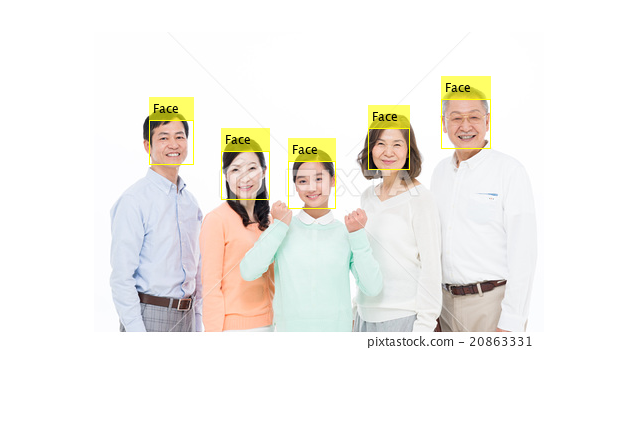

%识别并框出脸的区域
IFaces = insertObjectAnnotation(I, ...
'rectangle',bboxes,'Face');
imshow (IFaces);


%找出眼睛的数量
eyesDetector = ...
vision.CascadeObjectDetector(...
'ClassificationModel','EyePairSmall',...
'UseROI',true);

eyesCounter=1;
for i = 1:1:length(bboxes)
    temp2 = eyesDetector(I,bboxes(i,:));
    if ~isempty(temp2)
        bboxes3(eyesCounter,:) = temp;
        eyesCounter = eyesCounter+1;
    end
end

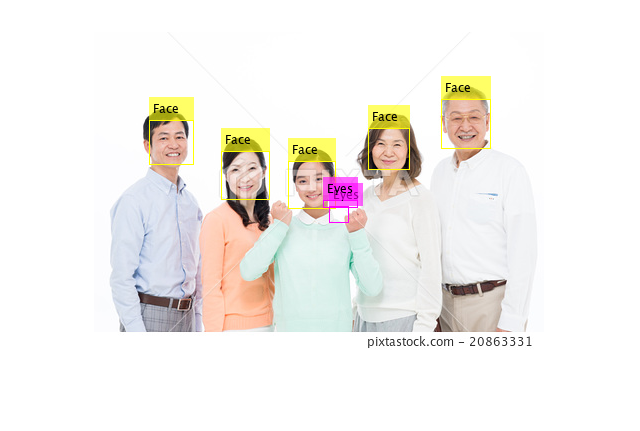

%识别并框出眼睛的区域
IEyes = insertObjectAnnotation (IFaces,...
 'rectangle',bboxes3,'Eyes',...
 'Color','magenta');
 imshow(IEyes)

%找出鼻子的数量
noseDetector = ...
vision.CascadeObjectDetector(...
'ClassificationModel','Nose',...
'UseROI',true);

noseCounter=1;
for i = 1:1:length(bboxes)
    temp = noseDetector(I,bboxes(i,:));
    if ~isempty(temp)
        bboxes4(noseCounter,:) = temp;
        noseCounter = noseCounter+1;
    end
end

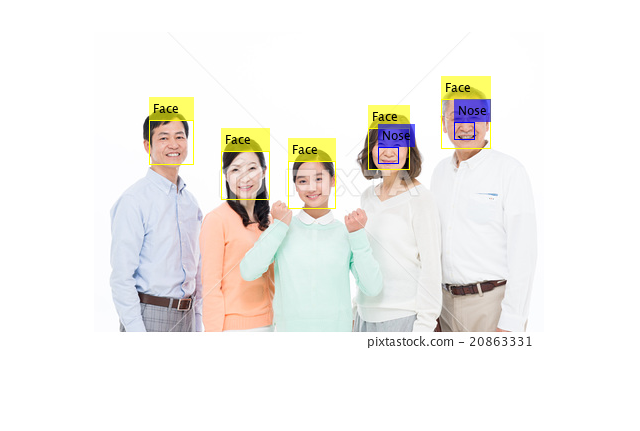

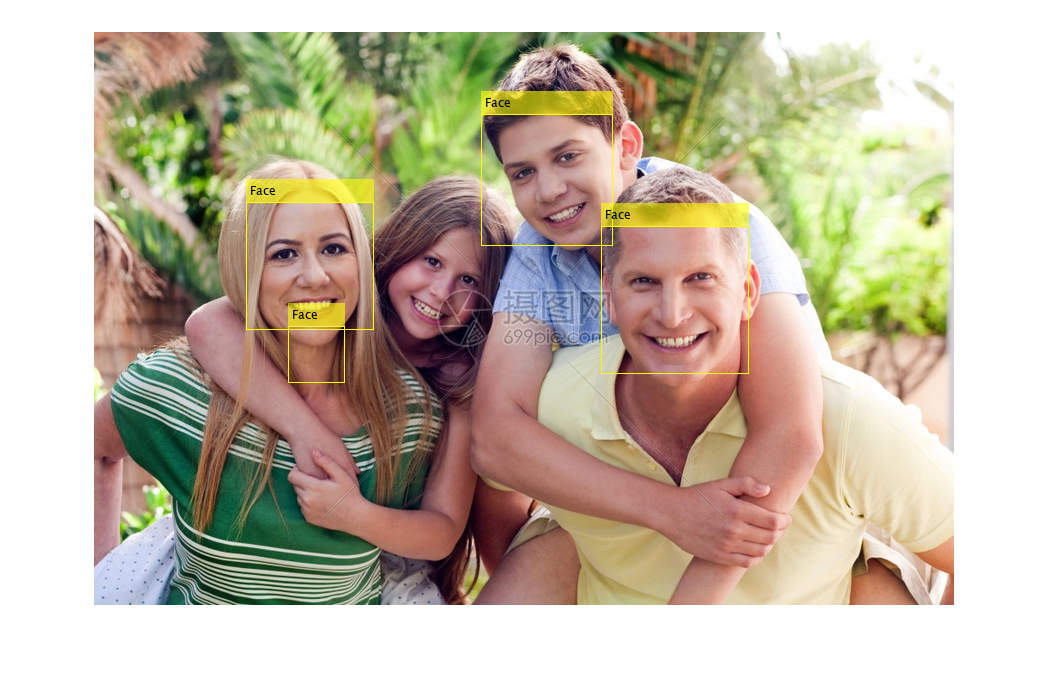

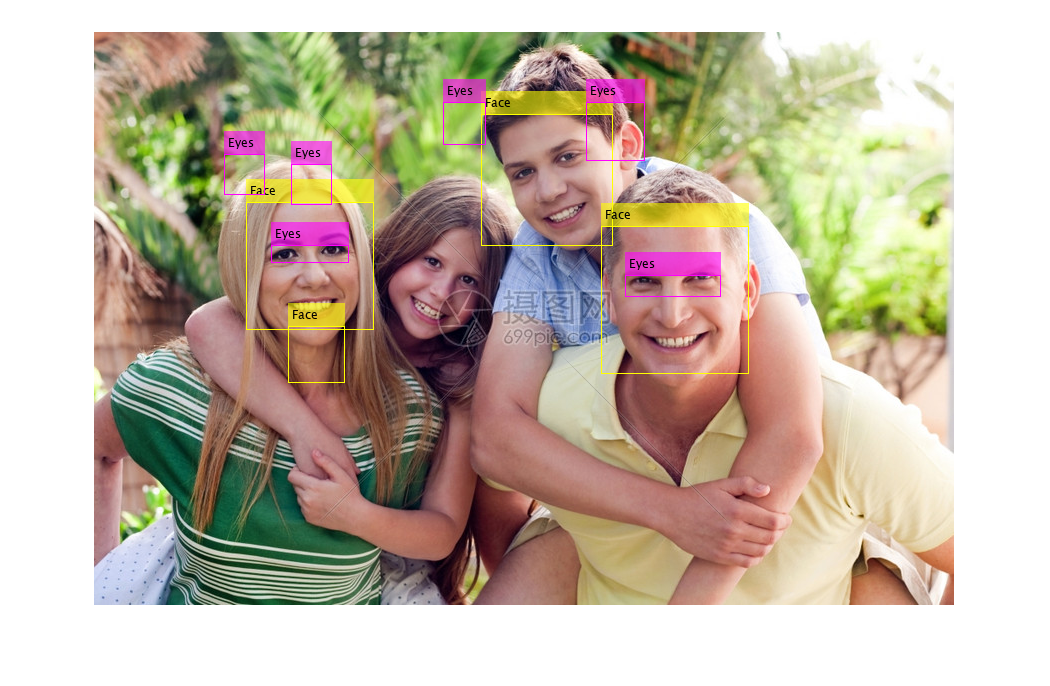

%识别并框出鼻子的区域
INose = insertObjectAnnotation (IFaces,...
 'rectangle',bboxes4,'Nose',...
 'Color','blue');
 imshow(INose)